# **Laborator 11 - Generarea unor cuadraturi de tip Gauss**

#### P1. Implementați funcții ce generează formule de cuadratură gaussiene pentru ponderile clasice date în tabela 1.

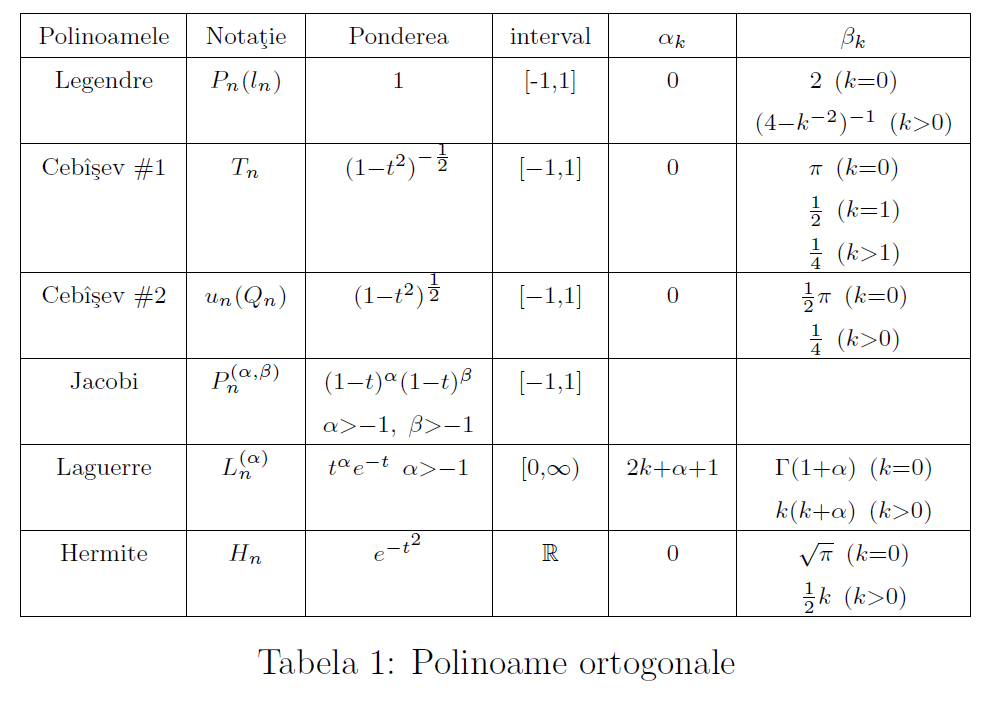

#### P2. Aproximați integrala dată printr-o formulă de cuadratură Gauss-Legendre și comparați rezultatul cu cel returnat de *quad*.

f = @(x)sin(x.^2);
a = -1; b = 1; n = 10;

I1 = quad(f, a, b);
[g_nodes, g_coeff] = Gauss_Legendre(n);
I2 = vquad(g_nodes, g_coeff, f);

fprintf("Aproximarea integralei prin Gauss-Legendre: %f", I2);

Aproximarea integralei prin Gauss-Legendre: 0.620537

fprintf("Aproximarea integralei prin quad: %f", I1);

Aproximarea integralei prin quad: 0.620537

#### P3. Calculați integralele date utilizând o formulă de cuadratură Gauss-Hermite.

f = @(x)exp(-(x.^2)) .* sin(x);
g = @(x)exp(-(x.^2)) .* cos(x);

[g_nodes, g_coeff] = Gauss_Hermite(n);
I1 = vquad(g_nodes, g_coeff, f);
I2 = vquad(g_nodes, g_coeff, g);

fprintf("Aproximarea primei integrale:");

Aproximarea primei integrale:

disp(I1);

  -1.8721e-16




fprintf("Aproximarea celei de-a doua integrale:");

Aproximarea celei de-a doua integrale:

disp(I2);

    1.1059

